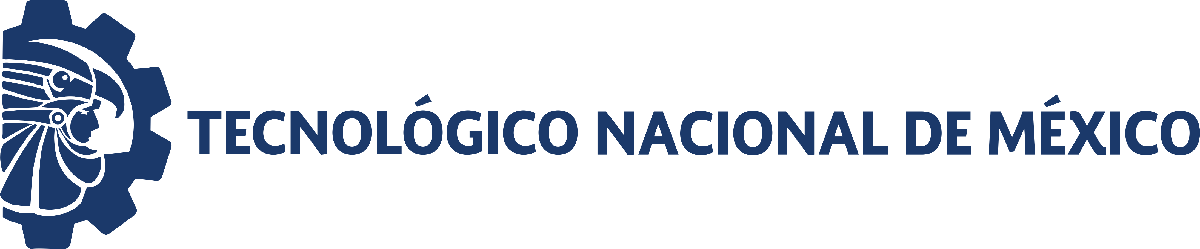                                 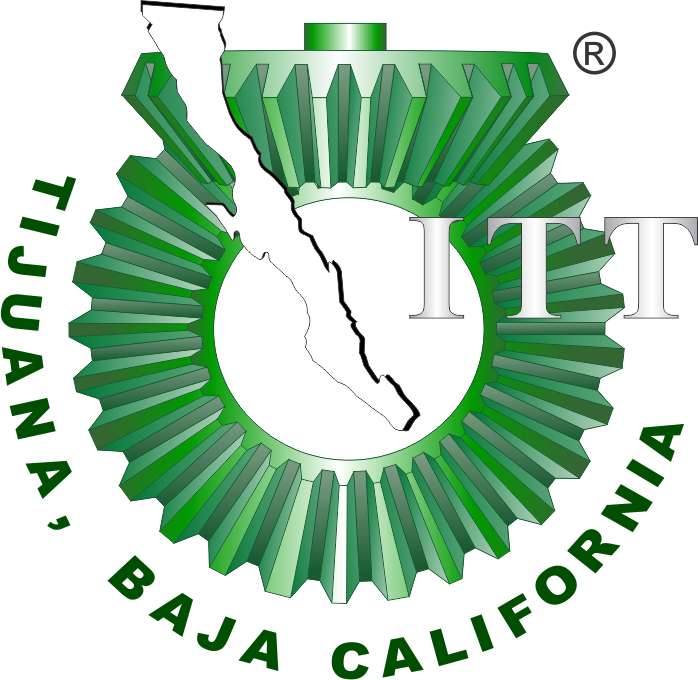

# Proyecto: Metabolismo Celular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

Nombre del alumno: **María Belén Galindo Ramírez, Ana Kamila Valle Z. Flores**

Número de control: **22211755, 22211769**

Correo institucional: **l22211755@tectijuana.edu.mx, l22211769@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Descripción

El metabolismo celular representa la red compleja de reacciones bioquímicas que permiten a la célula transformar nutrientes en energía y componentes estructurales. En este modelo, el proceso se centra en la cinética enzimática, donde una enzima facilita la conversión de un sustrato en un producto final indispensable para las funciones celulares.

El modelo matemático describe la dinámica de una reacción metabólica que involucra una *Enzima-Sustrato (x), *un* Sustrato (z)* y un* Producto Final (y)*.

*x(t) (Enzima-Sustrato)*: Representa la concentración del complejo formado por la unión de la enzima y el sustrato. Sus unidades se expresan típicamente en Milimolar (mM).

*y(t) (Producto Final)*: Es la concentración de la sustancia resultante de la reacción enzimática. Se mide en las mismas unidades de concentración (mM) .

*z(t) (Sustrato)*: Es la concentración del reactivo disponible que ser· transformado por la enzima.

El sistema está definido por las siguientres tres ecuaciones diferenciales ordinarias (EDO) no lineales de primer orden:


$$\dot{x} =\textrm{axz}-\textrm{bx}$$



$$\dot{y} =\textrm{cyz}-\textrm{dy}$$



$$\dot{z} =-\textrm{exyz}$$


donde los parámetros del sistema definen la cinética de las interacciones metabólicas. En términos biológicos, *a* representa la afinidad y tasa de formación del complejo *enzima-sustrato (x)*, mientras que *b *mide la velocidad de su disociación o pérdida. Por otro lado,* c* indica la eficiencia con la que el sustrato se transforma en el *producto final* (y), y *d* es la tasa de depuración o consumo de dicho producto. Finalmente, el parámetro *e *cuantifica el agotamiento constante del *sustrato (z)* derivado de la actividad conjunta del sistema.

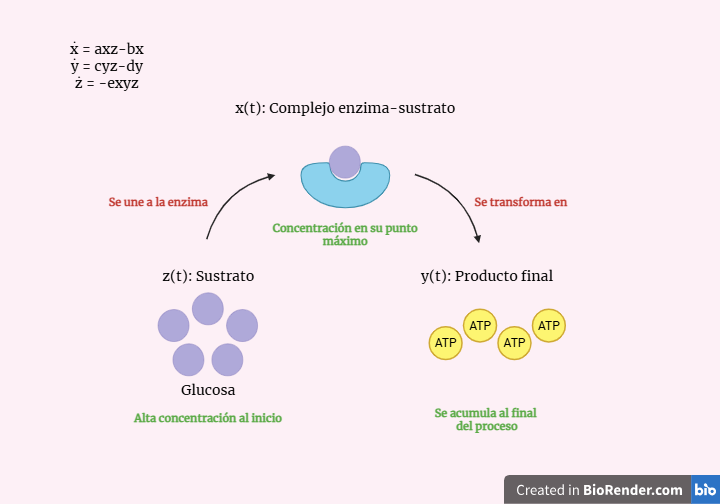

Figura 1. Representación del sistema.

## Objetivo

Analizar la dinámica de un modelo matemático basado en ecuaciones diferenciales ordinarias (EDO) no lineales que describe la cinética enzimática del metabolismo celular, con el fin de determinar la viabilidad biológica del sistema, sus estados de reposo y su estabilidad local.

## Referencia

P. A. Valle, Syllabus para Gemelos Digitales, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2025. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/)

## Datos experimentales

clc; clear; close all; warning('off', 'all')

archivo = 'data3 (1).csv'; 
titulo = 'Metabolismo Celular: Datos vs Eureqa';

[tm,xm,ym,zm] = getdata(archivo);

x_smooth = smoothdata(xm, 'gaussian', 5);
y_smooth = smoothdata(ym, 'gaussian', 5);
z_smooth = smoothdata(zm, 'gaussian', 5);

x_norm = x_smooth / max(x_smooth);
y_norm = y_smooth / max(y_smooth);
z_norm = z_smooth / max(z_smooth);

datos_procesados = table(tm, x_norm, y_norm, z_norm, 'VariableNames', {'t', 'x', 'y', 'z'});
nombre_nuevo_archivo = 'data3_normalizada_suavizada.csv';

p = [0.048804602255006; 
      0.038794721115301; 
      0.0847288571396478; 
      0.0519367517188392; 
      0.0104829408272899];

## Bioestadísticos

mdl = eureqaEDOSistema(tm, x_norm, y_norm, z_norm, p);

Cantidad de datos: 33
Cantidad de parámetros: 5
Grados de libertad: 28
Valor t-student: 2.0484
Alpha: 0.05
 
    Parameters    Estimate        SE           MoE                CI95              Pvalue  
    __________    ________    __________    __________    ____________________    __________

      {'a'}       0.049199     0.0023282     0.0047692     0.04443    0.053968    9.5325e-19
      {'b'}       0.039272     0.0021092     0.0043204    0.034952    0.043593    2.6228e-17
      {'c'}       0.070186     0.0029483     0.0060393    0.064146    0.076225    4.0212e-20
      {'d'}        0.04032     0.0026505     0.0054292     0.03489    0.045749    4.5905e-15
      {'e'}       0.010495    0.00020925    0.00042864    0.010066    0.010923    5.7698e-29

R-cuadrada ordinaria: 0.99783
Suma

## Eureqa

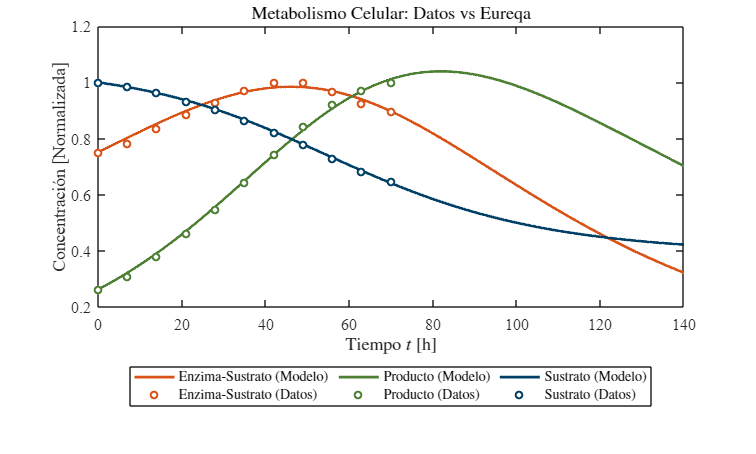

p_opt = mdl.Coefficients.Estimate;

x0 = x_norm(1);
y0 = y_norm(1);
z0 = z_norm(1);
t_max = max(tm);
dt = 0.1; 

[te, xe, ye, ze] = eureqaHeun(x0, y0, z0, 2*t_max, dt, p_opt);

plotdata(tm, x_norm, y_norm, z_norm, te, xe, ye, ze, titulo);
exportgraphics(gcf, 'eureqa.pdf', 'ContentType', 'vector')

## Puntos de equilibrio

syms x y z
syms a b c d e

dx_dt = a*x*z - b*x == 0;
dy_dt = c*y*z - d*y == 0;
dz_dt = -e*x*y*z == 0;

E = solve([dx_dt, dy_dt, dz_dt], [x, y, z]);

fprintf(['Puntos de equilibrio del sistema: ', num2str(length(E.x)), '\n\n']);

Puntos de equilibrio del sistema: 3




for i = 1:length(E.x)
    fprintf('eq%d:\n', i);
    disp([E.x(i); E.y(i); E.z(i)]);
end

eq1:


$$\left(\begin{array}{c} 0\\ 0\\ \frac{b}{a} \end{array}\right)$$

eq2:


$$\left(\begin{array}{c} 0\\ 0\\ \frac{d}{c} \end{array}\right)$$

eq3:


$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

## Matriz Jacobiana

dx_dt = a*x*z - b*x;
dy_dt = c*y*z - d*y;
dz_dt = -e*x*y*z;
J = jacobian([dx_dt,dy_dt,dz_dt],[x,y,z]);
fprintf('Matriz Jacobiana: \n'); disp(J)

Matriz Jacobiana: 


$$\left(\begin{array}{ccc} a\,z-b & 0 & a\,x\\ 0 & c\,z-d & c\,y\\ -e\,y\,z & -e\,x\,z & -e\,x\,y \end{array}\right)$$

## Condiciones de estabilidad 

equilibria(p);

Equilibria  |  x*         |  y*         |  z*        |
------------------------------------------------------
eq1         ( 1.000e+00 ,  0.000e+00 ,  7.949e-01)
eq2         ( 0.000e+00 ,  1.000e+00 ,  6.130e-01)
eq3         ( 0.000e+00 ,  0.000e+00 ,  0.000e+00)

Equilibria  | Lambda 1        | Lambda 2        | Lambda 3        | Stability 
----------------------------------------------------------------------------------------
eq1         |       0.000e+00 |      -0.000e+00 |       1.541e-02 | unstable  
eq2         |       0.000e+00 |      -0.000e+00 |      -8.879e-03 | unidentified
eq3         |      -5.194e-02 |      -3.879e-02 |      -0.000e+00 | unidentified
----------------------------------------------------------------------------------------



## Datos de la simulación

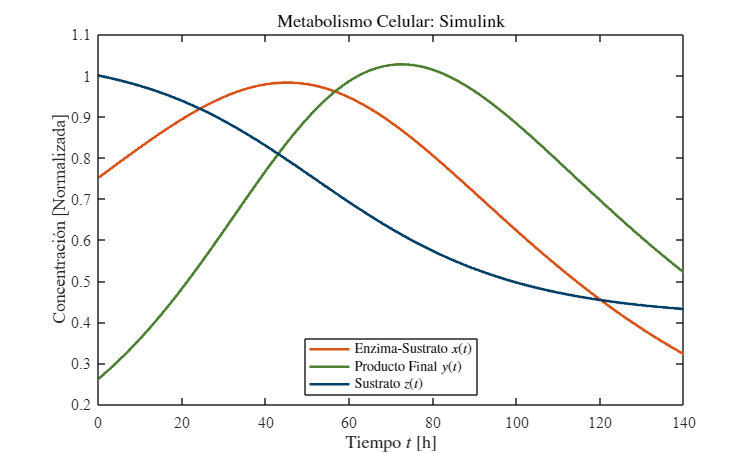

tend='140';
file='sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
titulo = 'Metabolismo Celular: Simulink';
set_param('sistema/S1','sw','1');
s=sim(file,parameters);
plotsimulink(s.t,s.x,s.y,s.z,titulo)
exportgraphics(gcf, 'simulink.pdf', 'ContentType', 'vector')

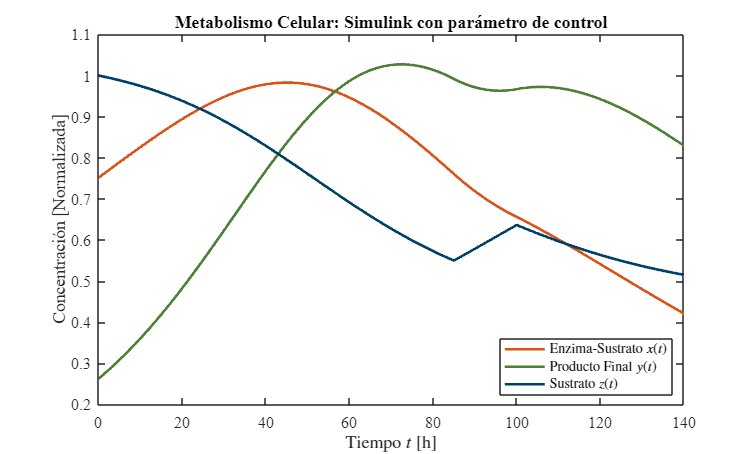

titulo = 'Metabolismo Celular: Simulink con parámetro de control';
set_param('sistema/S1','sw','0');
s=sim(file,parameters);
plotsimulink(s.t,s.x,s.y,s.z,titulo)
exportgraphics(gcf, 'simulink_control.pdf', 'ContentType', 'vector')

## Función

function [t, x, y, z] = getdata(file)
    datos = readtable(file);
    t = datos.t;
    x = datos.x;
    y = datos.y;
    z = datos.z;
end

function mdl = eureqaEDOSistema(te, xe, ye, ze, p0)
    x0 = xe(1); 
    y0 = ye(1); 
    z0 = ze(1);
    
    
    function y_calc = model(par, T_pred)
        t_orig = T_pred(1 : length(T_pred)/3);
        dt = 0.1;
        time = (0:dt:max(t_orig))';
        n = round(max(t_orig)/dt);
        
        x = zeros(length(time), 1); x(1) = x0;
        y = zeros(length(time), 1); y(1) = y0;
        z = zeros(length(time), 1); z(1) = z0;
        
        a = par(1); b = par(2); c = par(3); 
        d = par(4); e = par(5);
        
        for i = 1:n 
            fx = a*x(i)*z(i) - b*x(i); 
            fy = c*y(i)*z(i) - d*y(i);
            fz = -e*x(i)*y(i)*z(i);
            
            xn = x(i) + fx * dt;
            yn = y(i) + fy * dt;
            zn = z(i) + fz * dt;
            
            fxn = a*xn*zn - b*xn;
            fyn = c*yn*zn - d*yn;
            fzn = -e*xn*yn*zn;
            
            x(i+1) = x(i) + (fx + fxn) * dt / 2;
            y(i+1) = y(i) + (fy + fyn) * dt / 2;
            z(i+1) = z(i) + (fz + fzn) * dt / 2;
            
        end
        
        x_interp = interp1(time, x, t_orig);
        y_interp = interp1(time, y, t_orig);
        z_interp = interp1(time, z, t_orig);
        
        y_calc = [x_interp; y_interp; z_interp];
    end

    DatosReales = [xe; ye; ze];
    T_pred_input = [te; te; te]; 
    
    mdl = fitnlm(T_pred_input, DatosReales, @model, p0);
    
    NombresParametros = {'a'; 'b'; 'c'; 'd'; 'e'};
    biostats(mdl, NombresParametros);
end

function [time, x, y, z] = eureqaHeun(x0, y0, z0, t_max, dt, p)
    time = (0:dt:t_max)'; 
    n = round(t_max/dt);
    
    x = zeros(length(time), 1); x(1) = x0;
    y = zeros(length(time), 1); y(1) = y0;
    z = zeros(length(time), 1); z(1) = z0;
     
    a = p(1); b = p(2); c = p(3); 
    d = p(4); e = p(5);
    
    for i = 1:n 
        fx = a*x(i)*z(i) - b*x(i); 
        fy = c*y(i)*z(i) - d*y(i);
        fz = -e*x(i)*y(i)*z(i);
        
        xn = x(i) + fx * dt;
        yn = y(i) + fy * dt;
        zn = z(i) + fz * dt;
        
        fxn = a*xn*zn - b*xn; 
        fyn = c*yn*zn - d*yn;
        fzn = -e*xn*yn*zn;
        
        x(i+1) = x(i) + (fx + fxn) * dt / 2;
        y(i+1) = y(i) + (fy + fyn) * dt / 2;
        z(i+1) = z(i) + (fz + fzn) * dt / 2;
        
        if x(i+1) < 0, x(i+1) = 0; end
        if y(i+1) < 0, y(i+1) = 0; end
        if z(i+1) < 0, z(i+1) = 0; end
    end
end

function biostats(mdl, Parameters)
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    
    CI95 = coefCI(mdl, alpha);
    dof = mdl.DFE;
    tval = tinv(1 - alpha/2, dof);
    MoE = SE * tval;
    
    Results = table(Parameters, Estimate, SE, MoE, CI95, Pvalue);
    disp(['Cantidad de datos: ', num2str(mdl.NumObservations)]);
    disp(['Cantidad de parámetros: ', num2str(mdl.NumCoefficients)]);
    disp(['Grados de libertad: ', num2str(dof)]);
    disp(['Valor t-student: ', num2str(tval)]);
    disp(['Alpha: ', num2str(alpha)]);
    disp(' ');
    disp(Results);
    
    R2o = mdl.Rsquared.Ordinary;
    SSE = mdl.SSE;
    AICc = mdl.ModelCriterion.AICc;
    
    fprintf(['R-cuadrada ordinaria: ', num2str(R2o)]);
    fprintf(['\nSuma residual de cuadrados: ', num2str(SSE)]);
    fprintf(['\nCriterio de información de Akaike ajustado: ', num2str(AICc)]);
    fprintf('\n\n');
end

function plotdata(t, x, y, z, ts, xs, ys, zs, titulo)
    set(figure(), 'color', 'w', 'Name', titulo);
    FS = 12; 

    set(gcf, 'Units', 'Centimeters', 'Position', [1, 1, 20, 12]);

    c_x = [0.8500, 0.3250, 0.0980];
    c_y = [0.3, 0.5, 0.2];          
    c_z = [0, 0.25, 0.4];            

    hold on; box on; grid off;
    
    plot(ts, xs, '-', 'LineWidth', 2, 'Color', c_x)
    plot(t, x, 'o', 'LineWidth', 1.5, 'MarkerSize', 5, 'Color', c_x, 'MarkerFaceColor', 'w')

    plot(ts, ys, '-', 'LineWidth', 2, 'Color', c_y)
    plot(t, y, 'o', 'LineWidth', 1.5, 'MarkerSize', 5, 'Color', c_y, 'MarkerFaceColor', 'w')
    
    plot(ts, zs, '-', 'LineWidth', 2, 'Color', c_z)
    plot(t, z, 'o', 'LineWidth', 1.5, 'MarkerSize', 5, 'Color', c_z, 'MarkerFaceColor', 'w')

    title(titulo, 'Interpreter', 'Latex', 'FontSize', 16, 'FontWeight', 'bold');
    xlabel('Tiempo $t$ [h]', 'Interpreter', 'Latex', 'FontSize', FS)    
    ylabel('Concentración [Normalizada]', 'Interpreter', 'Latex', 'FontSize', FS)        
    legend('Enzima-Sustrato (Modelo)', 'Enzima-Sustrato (Datos)', ...
           'Producto (Modelo)', 'Producto (Datos)', ...
           'Sustrato (Modelo)', 'Sustrato (Datos)', ...
           'Interpreter', 'Latex', 'Location', 'southoutside', 'NumColumns', 3)
           
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
end

function plotsimulink(t,x,y,z,titulo)
    set(figure(), 'color', 'w', 'Name', titulo);
    FS = 12; 
 
    set(gcf, 'Units', 'Centimeters', 'Position', [1, 1, 20, 12]);

    c_x = [0.8500, 0.3250, 0.0980];
    c_y = [0.3, 0.5, 0.2];          
    c_z = [0, 0.25, 0.4];

    hold on; box on; grid off;
    

    plot(t, x, '-', 'LineWidth', 2, 'Color', c_x)
    plot(t, y, '-', 'LineWidth', 2, 'Color', c_y)
    plot(t, z, '-', 'LineWidth', 2, 'Color', c_z)
    
 
    title(titulo, 'Interpreter', 'Latex', 'FontSize', 16, 'FontWeight', 'bold');
    xlabel('Tiempo $t$ [h]', 'Interpreter', 'Latex', 'FontSize', FS)    
    ylabel('Concentración [Normalizada]', 'Interpreter', 'Latex', 'FontSize', FS)       
    legend('Enzima-Sustrato $x(t)$', 'Producto Final $y(t)$', 'Sustrato $z(t)$', ...
           'Interpreter', 'Latex', 'Location', 'best')
           
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
end

function equilibria(p)
    a = p(1); b = p(2); c = p(3); 
    d = p(4); e = p(5);


    e1 = [1; 0; b/a];                
    e2 = [0; 1; d/c];                
    e3 = [0; 0; 0];              
            
    
    E = [e1, e2, e3]; 
    E = double(E)'; 
    E(E > -1e-12 & E < 1e-12) = 0; 
    names = {'eq1'; 'eq2'; 'eq3'};
    
 
    fprintf('\n%-11s | %-11s | %-11s | %-11s|\n', 'Equilibria', ' x*', ' y*', ' z*');
    fprintf('------------------------------------------------------\n');
    for i = 1:length(E)
        fprintf('%-11s (%10.3e , %10.3e , %10.3e)\n', names{i}, E(i,1), E(i,2), E(i,3));
    end
    fprintf('\n');
    
    x = E(:,1); 
    y = E(:,2); 
    z = E(:,3); 
    
 
    lr = zeros(length(E), 3);
    li = zeros(length(E), 3);
    stability = cell(length(E), 1);

  
    fprintf('%-11s | %-15s | %-15s | %-15s | %-10s\n', 'Equilibria', 'Lambda 1', 'Lambda 2', 'Lambda 3', 'Stability');
    fprintf('----------------------------------------------------------------------------------------\n');

    for i = 1:length(E)
        
        J = [ a*z(i) - b,          0,                 a*x(i);
              0,                   c*z(i) - d,        c*y(i);
             -e*y(i)*z(i),        -e*x(i)*z(i),      -e*x(i)*y(i) ];
        

        eigenvals = eig(J);
       
        lr(i,:) = real(eigenvals); 
        lr(lr > -1e-12 & lr < 1e-12) = 0;
        
        li(i,:) = imag(eigenvals);
     
        if all(lr(i,:) < 0)
            stability{i,1} = 'stable';
        elseif any(lr(i,:) > 0)
            stability{i,1} = 'unstable';
        else
            stability{i,1} = 'unidentified';
        end

  
        fprintf('%-11s | %15.3e | %15.3e | %15.3e | %-10s\n', ...
            names{i}, eigenvals(1), eigenvals(2), eigenvals(3), stability{i,1});
            
    end
    fprintf('----------------------------------------------------------------------------------------\n\n');
end